% PI controller
t1 = 0.001 

t1 = 1.0000e-03

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



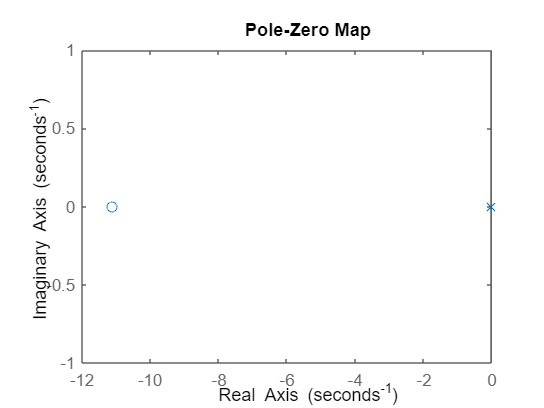

Ki = 10 ;
Kp = 0.9;


C_s = Kp * ((s + (Ki/Kp))/s);
pzmap(C_s)

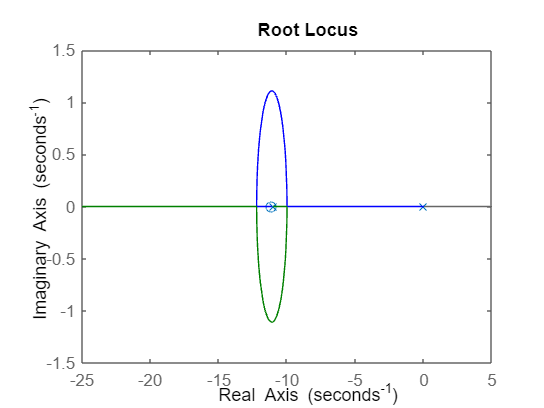


T_s = C_s * G_w_small;

rlocus(T_s)

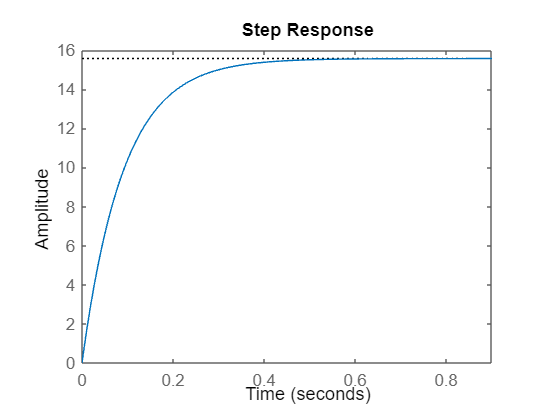


step(G_w_small)

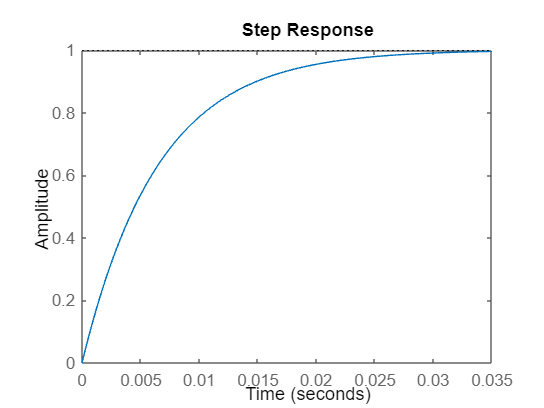


step(feedback(T_s, 1))


% Z transform
C_Z_tustin = c2d(C_s, t1, 'tustin')

C_Z_tustin =
 
  0.905 z - 0.895
  ---------------
       z - 1
 
Sample time: 0.001 seconds
Discrete-time transfer function.



G_Z = c2d(G_w_small,t1,'zoh')

G_Z =
 
    0.1703
  ----------
  z - 0.9891
 
Sample time: 0.001 seconds
Discrete-time transfer function.




T_Z_tustin = C_Z_tustin * G_Z

T_Z_tustin =
 
    0.1541 z - 0.1524
  ----------------------
  z^2 - 1.989 z + 0.9891
 
Sample time: 0.001 seconds
Discrete-time transfer function.



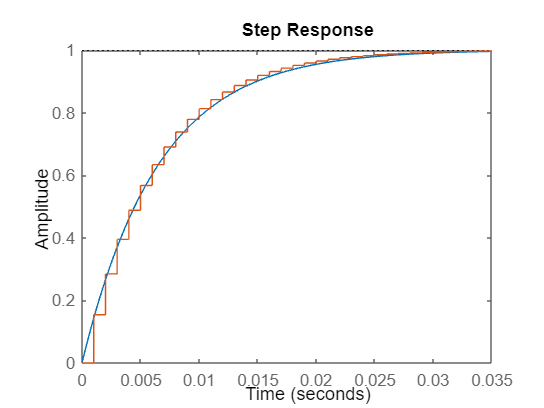


step(feedback(T_s,1))
hold on
step(feedback(T_Z_tustin, 1))